ZIE MM MATLAB kurzus

# Vezérlési szerkezetek

## Témák:

- vezérlési szerkezetek

- elágazások

- ciklusok

- függvények

clc; clear; close all;

## Vezérlési szerkezetek (control flow)

Egy program futtatásakor a kód fentről lefele, sorról sorra kerül kiértékelésre. A vezérlési szerkezetek olyan eszközök egy programnyelvben, melyek megtörik ezt a lineáris futtatást. A törés lehet csak néhány sor kihagyása, vagy akár sorok ismétlése is.

Három alap vezérlési szerkezet létezik:

- feltételes elágazás

- feltételes ciklus

- számlálós ciklus

### Feltételes elágazás (if statement)

Az elágazás az egyik legalapvetőbb vezérlési szerkezet. Alkalmazásával a program képes lehet összetett eseteket kezelni, különböző értékeket különböző módon feldolgozni. Ez a szerkezet majd minden programnyelvben nagyon hasonlóan néz ki.

Egyszerű elágazás (IF):

a = 4;
b = 3;
if a > b % logikai feltétel
    a % futtatandó kód, ha feltétel IGAZ
end

Bővített elágazás (IF-ELSE):

if a > b % logikai feltétel
    a % futtatandó kód, ha feltétel IGAZ
else
    b % futtatandó kód, ha feltétel HAMIS
end

Összetett elágazás (IF-ELSEIF-ELSE):

if a > b % logikai feltétel
    a % futtatandó kód, ha feltétel IGAZ
elseif a < b % alternatív logikai feltétel
    b % futtatandó kód, ha alternatív feltétel IGAZ
else
    [a,b] % futtatandó kód, ha minden feltétel HAMIS
end

Összetett elágazásokhoz bármennyi alternatív feltételt meg lehet adni, de csak az első IGAZ feltételhez tartozó kód fog lefutni. Emellett nem tanácsos sok feltételből álló elágazásokat írni mert sokszoros ismétlés esetén a kiértékelés jelentős időt vehet igénybe. (Alternatíváról később lesz szó.)

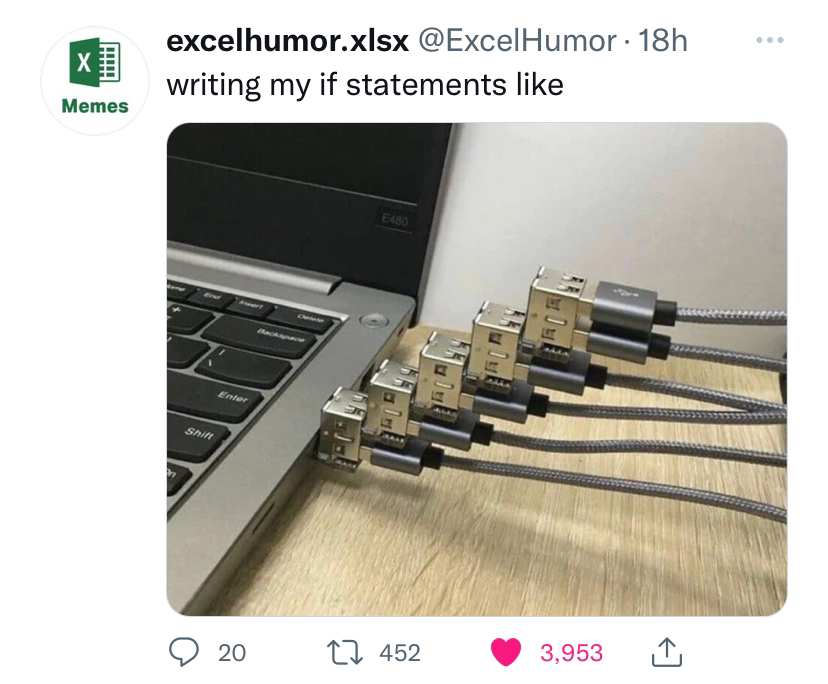

### Feltételes ciklus (while loop)

A feltételes ciklusoknak alapvetően két fajtája létezik:

- elöltesztelő (while do)

- hátultesztelő (do while)

Feltételes ciklusokat akkor érdemes használni, ha előre nem lehet megmondani, hogy hányszor kell a műveletet ismételni.

Több programozási nyelvben (pl.: C, C++) is beépített nyelvi szerkezet van a két külön mintára, MATLAB-ban csak az elöltesztelő verzió támogatott, ugyanakkor a minták kis csalással egymással helyettesíthetők.

Az elöltesztelő ciklusok esetén a feltétel miden iteráció előtt kiértékelésre kerül, és csak akkor indul a következő, ha a feltétel IGAZ. Az is előfordulhat, hogy a ciklus teste egyszer sem fut le (ha feltétel már az első iteráció előtt is HAMIS).

A hátultesztelő verzióban a ciklus teste legalább egyszer lefut amikor a program belép a ciklusba. Ezután a feltétel kiértékelődik és a ciklus újraindul ha a feltétel IGAZ, egyébként a program tovább lép.

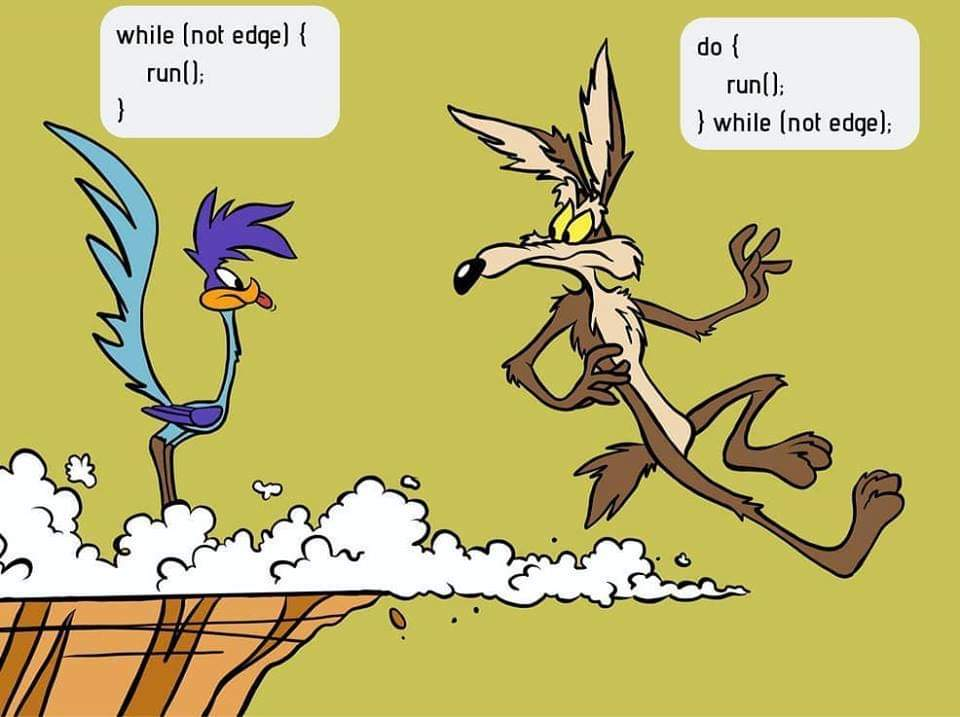

Sima elöltesztelő ciklus (while loop):

while a > b % ciklus feltétel
    b = b + 1; % ciklus test
end
b

A ciklus feltételét körültekintően kell meghatározni, mert egy hibás feltétel végtelen ciklust okozhat:

% while true
%     a = a + 1;
% end

Hátultesztelő ciklus (do while loop) helyettesítése elöltesztelővel:

while true % "végtelen" ciklus feltétel
    b = b + 1 % ciklus test
    if a <= b % kilépési feltétel
        break % aktuális ciklus megtörése
    end
end

### Számlálós ciklus (for loop)

A számlálós ciklusoknak is főleg két fajtája létezik:

- for loop

- for-each loop

A számlálós csiklus (for loop) valójában csak egy változata a feltételes ciklusoknak (ez nagyon jól látszik például a C nyelben használatos szintaktikán). A legegyszerűbb esetben arra használható, hogy ismert számú iterációval fusson a program egy része.

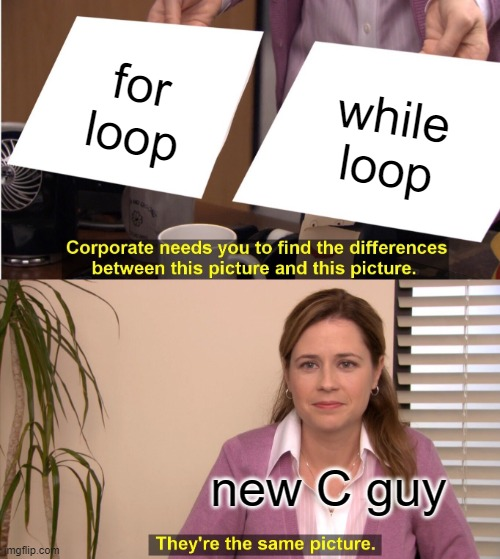

MATLAB-ban a számlálós ciklusnak egy magasabb szintű változata a "for-each" ciklus típus érhető el, amely nem egy számlálót léptet, hanem egy megadott iterálható adat elemein lépked végig. (Ugyan ezt a verziót tartalmazza például a Python nyelv is.) Természetesen szimulálható vele a sima számlálós ciklus is.

for i = [3,1,5,7,3,1,7] % ciklus változó + iterálható adat
    i
end

Sima számlálós ciklus szimulálása adott számú iterációhoz:

for i = 1:10 % iterálható tömb generálás tól:ig
    i
end

Iterációs index:

i = 1;
for num = [1,2,6,223,5,1,2]
    [i,num]
    i = i+1;
end

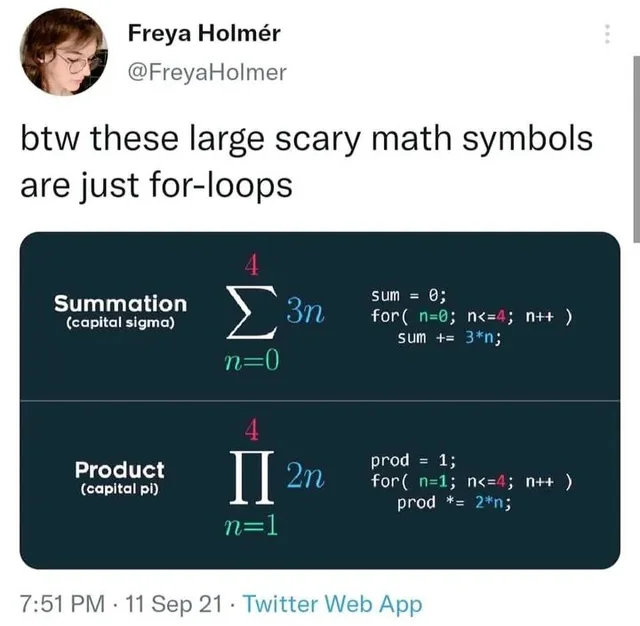

### Minta illesztés (switch statement / pattern matching)

A minta illesztő kifejezés egy több lépéses összetett elágazáshoz hasonló szerkezet. Legjobban akkor használható, ha egy változó konkrét lehetséges értékeit kell lekezelni. Általánosságban jobb teljesítményű és könnyebben olvasható megoldás mint ha 5-10 elágazás lenne összefűzve.

fruit = 'apple';

switch fruit
    case 'apple'
        fprintf('The input is an apple')
    case 'banana'
        fprintf('The input is a banana')
    case {'cucumber', 'potato'}
        fprintf('The input is vegetable')
    otherwise
        fprintf('The inputs is of unknown type')
end

### Kivétel kezelés (try-catch)

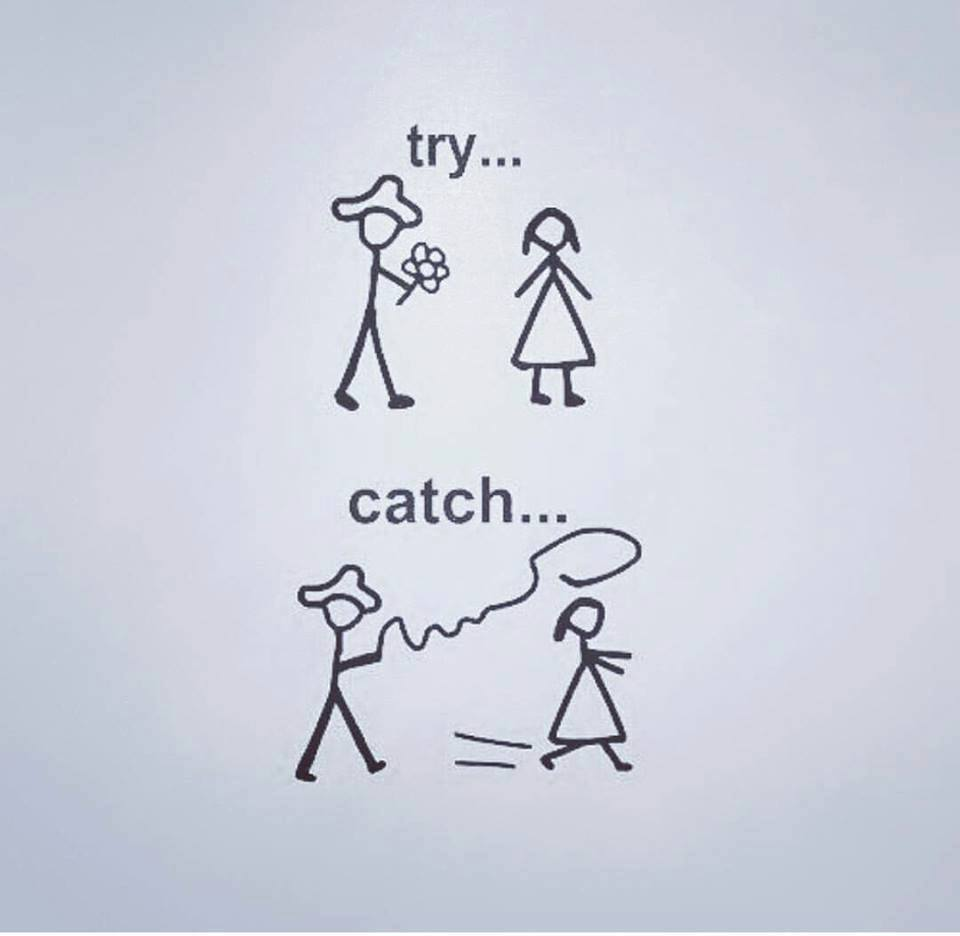 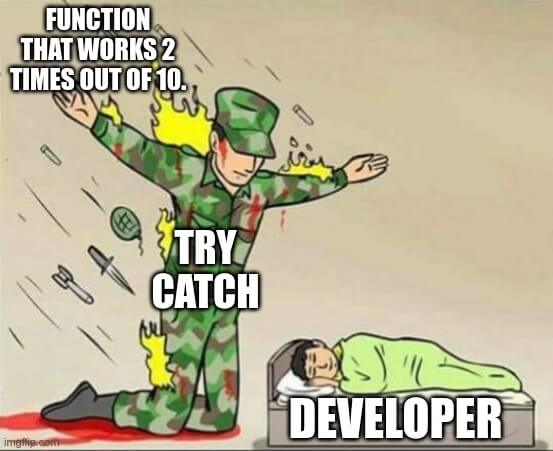

Egy program futása során különböző hibák fordulhatnak elő. Szemantikai hibák általában nem okozzák a program megállását, de akár ilyen is előfordulhat. A kivétel kezelő szerkezetek használhatók az előre jelezhető hibák kezelésére anélkül, hogy a teljes program leállna, és lehetővé teszik akár alternatív megoldások kipróbálását is hiba esetén.

try
    a = b;
catch ME
    warning("Some exception occured");
    a = 0;
end

## Függvények használata (function calls)

Az operátorok és vezérlési szerkezeteken felül MATLAB rengeteg beépített függvényt is tartalmaz. Ezek a függvények sokszor komplex számításokat tesznek lehetővé akár csak néhány sorban. A függvények neve programnyelvenként változik, itt szó szerint függvények.

Egy függvény egybefüggő művelet sort hajt végre. Általában van egy vagy több bemeneti adat. Sok függvény a bemeneti adatokból valamilyen kimenetet állít elő (pl.: matematikai számítások), de olyan függvények is vannak amik explicit kimeneti eredmény nélkül csak végrehajtanak valami eljárást (pl.: grafikon rajzolás).

Egyszerű függvény hívás:

c = sind(45) % függvénynév(bemenet1,bemenet2,...)

Bizonyos függvényeknek több kimenete is van. Ekkor lehetőség van mindegyiket kinyerni ha szükséges.

d = [2,65,1,7,9,445,127,823,2];
e = sort(d) % csak az első kimenet elfogása
[f,g] = sort(d) % mind két kimenet elfogása
[~,h] = sort(d) % ha valamelyik kimenetre nincs szükség